# NB-IoT simulation

## ofdm parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=42;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz


## simulation parameters

dataLength=numSC*numSym*2;
randomData=true;
nLoops=8;
filtersOn=false;
plotSpec=false;
maxSNR=22;
dopplerShift=00e3;

## transmission


%base message
if randomData
    messageBits= randi([0 1],dataLength,1)
else
    messageBits=ones(dataLength,1)
end

messageBits =      1
     1
     1
     1
     0
     1
     1
     1
     0
     0



%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      3
     3
     1
     3
     0
     0
     3
     1
     1
     2


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =   -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 - 0.7071i


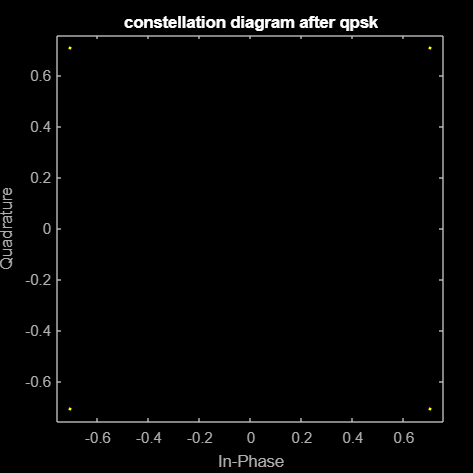

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

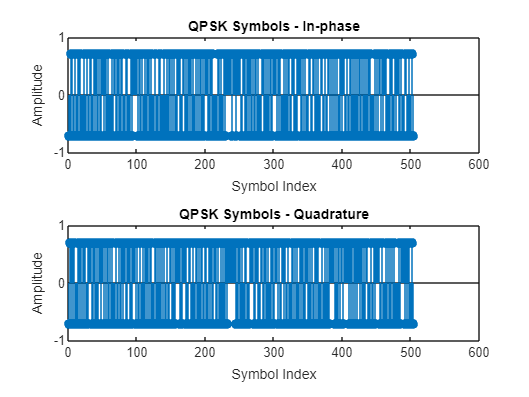


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


% numSC=12;% # subcarriers
% numSym=21;% # ofdm symbols
% SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
% t = (0:SPS-1) / samplingRate; %time vector

ofdmSignal = zeros(1, numSym * SPS);
cpLen=round(SPS/4);%cyclic prefix length
t=(0:length( (numSC+cpLen)*numSym)-1)' / samplingRate;


ofdmMatrix = zeros(numSC,numSym);%12x7 in nbiot
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =   -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i
  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.707

%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =    0.0000 - 0.1179i  -0.2357 - 0.2357i   0.1179 + 0.3536i   0.2357 - 0.2357i   0.2357 - 0.3536i   0.1179 + 0.2357i   0.1179 - 0.3536i  -0.2357 - 0.1179i   0.4714 + 0.5893i   0.0000 + 0.4714i  -0.1179 - 0.1179i   0.0000 + 0.1179i   0.0000 + 0.3536i  -0.1179 + 0.0000i   0.2357 + 0.2357i  -0.4714 - 0.3536i   0.0000 + 0.0000i   0.3536 + 0.0000i   0.1179 + 0.0000i  -0.1179 - 0.2357i   0.0000 + 0.1179i   0.0000 + 0.1179i  -0.2357 - 0.5893i   0.0000 - 0.3536i  -0.1179 + 0.4714i   0.0000 + 0.0000i  -0.1179 + 0.3536i  -0.1179 + 0.1179i  -0.1179 - 0.1179i   0.0000 + 0.1179i   0.0000 - 0.4714i  -0.1179 + 0.0000i   0.0000 + 0.0000i  -0.5893 + 0.0000i   0.0000 + 0.1179i  -0.3536 + 0.1179i  -0.2357 + 0.0000i  -0.1179 + 0.0000i  -0.4714 - 0.1179i  -0.1179 + 0.0000i   0.1179 - 0.2357i   0.1179 - 0.2357i
  -0.0747 + 0.2473i  -0.2788 - 0.1926i  -0.1179 + 0.0316i  -0.1768 - 0.0158i   0.2041 - 0.1179i   0.1021 - 0.0589i   0.2357 + 0.0000i   0.0158 - 0.1768i   0.1021 - 0.2630i  -0.1768 + 0.0158i   0.1

timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =    0.0000 - 0.1179i  -0.2357 - 0.2357i   0.1179 + 0.3536i   0.2357 - 0.2357i   0.2357 - 0.3536i   0.1179 + 0.2357i   0.1179 - 0.3536i  -0.2357 - 0.1179i   0.4714 + 0.5893i   0.0000 + 0.4714i  -0.1179 - 0.1179i   0.0000 + 0.1179i   0.0000 + 0.3536i  -0.1179 + 0.0000i   0.2357 + 0.2357i  -0.4714 - 0.3536i   0.0000 + 0.0000i   0.3536 + 0.0000i   0.1179 + 0.0000i  -0.1179 - 0.2357i   0.0000 + 0.1179i   0.0000 + 0.1179i  -0.2357 - 0.5893i   0.0000 - 0.3536i  -0.1179 + 0.4714i   0.0000 + 0.0000i  -0.1179 + 0.3536i  -0.1179 + 0.1179i  -0.1179 - 0.1179i   0.0000 + 0.1179i   0.0000 - 0.4714i  -0.1179 + 0.0000i   0.0000 + 0.0000i  -0.5893 + 0.0000i   0.0000 + 0.1179i  -0.3536 + 0.1179i  -0.2357 + 0.0000i  -0.1179 + 0.0000i  -0.4714 - 0.1179i  -0.1179 + 0.0000i   0.1179 - 0.2357i   0.1179 - 0.2357i
  -0.0747 + 0.2473i  -0.2788 - 0.1926i  -0.1179 + 0.0316i  -0.1768 - 0.0158i   0.2041 - 0.1179i   0.1021 - 0.0589i   0.2357 + 0.0000i   0.0158 - 0.1768i   0.1021 - 0.2630i  -0.


timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =    0.0000 - 0.1179i
  -0.0747 + 0.2473i
   0.0000 - 0.2041i
  -0.2357 - 0.1179i
  -0.2041 - 0.3220i
  -0.2788 - 0.3651i
   0.0000 + 0.3536i
   0.0431 - 0.1926i
   0.2041 + 0.0863i
   0.0000 + 0.1179i


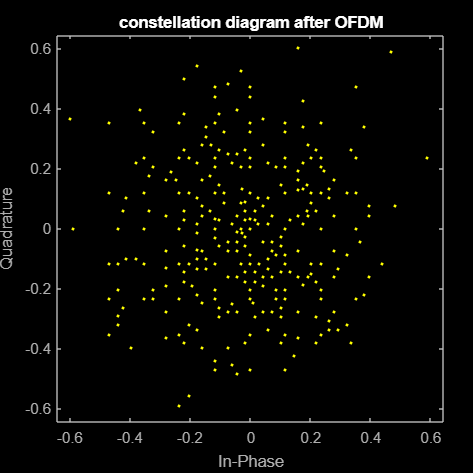

% plot ofdm signal

if plotSpec 
figure
window=hamming(7);
spectrogram(timeDomainSymbols,window,round(length(window)/2),BW)
end

figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

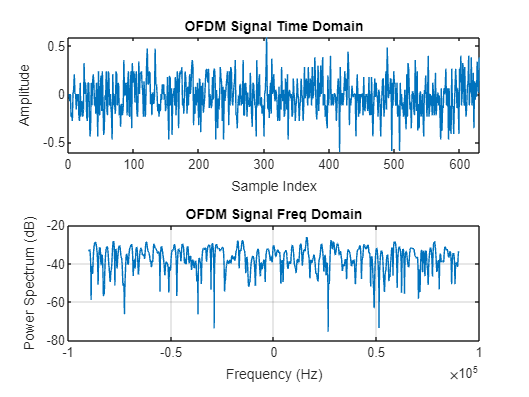


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

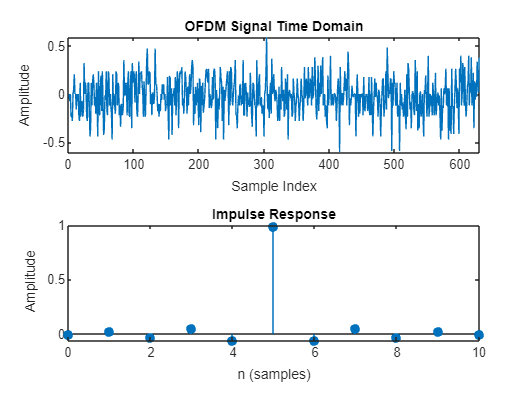

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(timeDomainSymbols, L);

rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

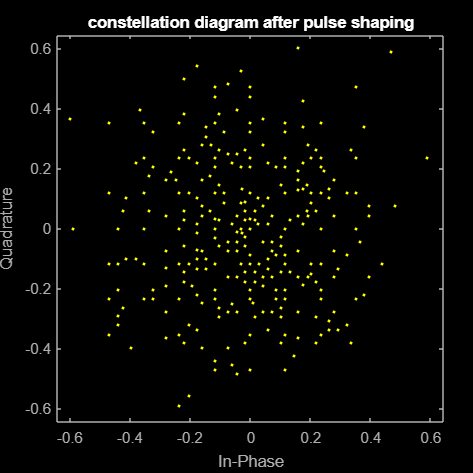

if filtersOn
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');
else
    txSignalShaped = txSignalUpsampled;

end

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

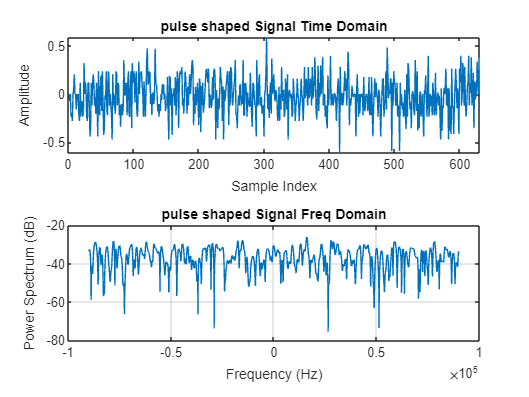


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

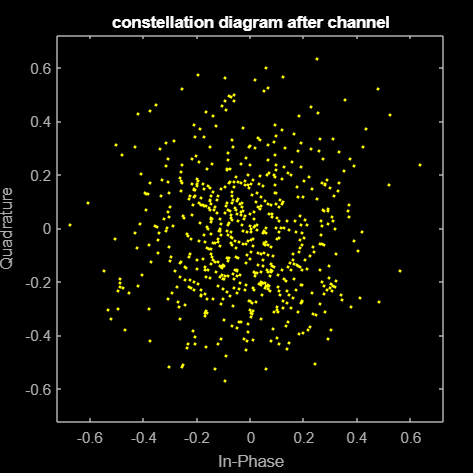

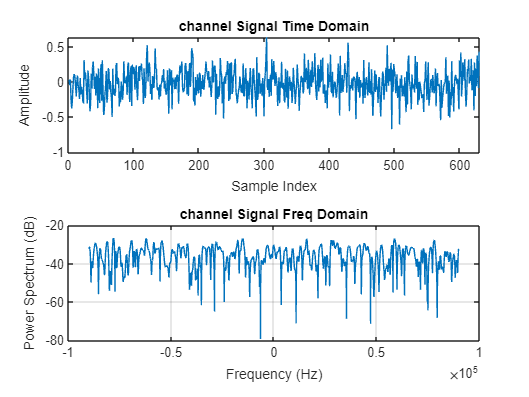

for counter=1:nLoops
%check filters, error rate is te hoog?

dopplerEffect = exp(1i * 2 * pi * dopplerShift * t);
txSignalDopplerShifted = txSignalUpsampled .* dopplerEffect';

SNR=20-(nLoops-counter);
% rxSignal=awgn(txSignalShaped,SNR);


rxSignal=awgn(txSignalDopplerShifted,SNR);
% rxSignal=txSignalShaped;

if counter==nLoops %only plot in last loop
    % Plot the time domain signal after channel
    figure
    scatterplot(rxSignal)
    title('constellation diagram after channel');
    
    % Plot the time domain signal
    figure;
    subplot(2,1,1);
    plot(real(rxSignal));
    title('channel Signal Time Domain');
    xlabel('Sample Index');
    ylabel('Amplitude');
    
    [pxx,f] = pspectrum(rxSignal,samplingRate);
    subplot(2,1,2);
    plot(f,pow2db(pxx))
    grid on
    title('channel Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

## receiver

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
if filtersOn
    matchedFilter = rcosdesign(rolloff, span, L);
    rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
else
    rxSignalFiltered = rxSignal;

end

rxSignalFiltered

rxSignalFiltered =   -0.1251 - 0.2672i
  -0.1522 + 0.2378i
   0.4709 - 0.2951i
  -0.3343 + 0.1104i
   0.0999 - 0.2847i
  -0.1267 - 0.2034i
  -0.0883 + 0.3314i
   0.0263 - 0.2055i
   0.1701 + 0.2855i
   0.0750 + 0.3503i


rxSignalFiltered =    0.0915 - 0.3419i
   0.0746 + 0.0898i
  -0.0893 - 0.1171i
  -0.0921 - 0.0412i
  -0.1799 - 0.5291i
  -0.2855 - 0.3482i
   0.2383 + 0.4282i
   0.2459 - 0.3584i
  -0.1135 - 0.0546i
   0.0503 + 0.2863i


rxSignalFiltered =    0.1182 - 0.2272i
  -0.2939 + 0.2701i
   0.1779 - 0.1755i
  -0.2966 + 0.1015i
  -0.1378 - 0.0934i
  -0.4267 - 0.2316i
   0.0949 + 0.4899i
   0.0430 - 0.3396i
   0.3618 + 0.2467i
  -0.0687 - 0.0005i


rxSignalFiltered =   -0.0467 - 0.1015i
  -0.1515 + 0.2515i
   0.0294 - 0.2767i
  -0.2616 - 0.2621i
  -0.3706 - 0.3680i
  -0.2138 - 0.1185i
  -0.0408 + 0.2494i
  -0.0241 - 0.1923i
   0.1087 - 0.0435i
   0.0890 + 0.2484i


rxSignalFiltered =   -0.0154 - 0.0066i
  -0.2197 + 0.2165i
  -0.0524 - 0.1180i
  -0.1084 + 0.0544i
  -0.2821 - 0.3559i
  -0.2586 - 0.4252i
   0.0281 + 0.4646i
   0.2274 - 0.1609i
   0.1790 + 0.0900i
   0.0645 + 0.1321i


rxSignalFiltered =   -0.1100 - 0.0602i
  -0.1211 + 0.3680i
   0.0370 - 0.4426i
  -0.2695 - 0.1425i
  -0.1085 - 0.3353i
  -0.3909 - 0.3939i
   0.0467 + 0.5003i
   0.1076 - 0.2386i
   0.2349 + 0.0141i
   0.0220 + 0.1462i


rxSignalFiltered =   -0.0423 - 0.1148i
  -0.0207 + 0.2656i
   0.0713 - 0.1941i
  -0.1058 - 0.0626i
  -0.3070 - 0.1840i
  -0.3428 - 0.3123i
   0.0128 + 0.4081i
  -0.1446 - 0.0943i
   0.0830 + 0.1576i
  -0.1435 + 0.0266i


rxSignalFiltered =    0.0297 - 0.1359i
  -0.0461 + 0.1744i
   0.0342 - 0.2064i
  -0.2564 - 0.1244i
  -0.3787 - 0.3002i
  -0.2610 - 0.3366i
  -0.0657 + 0.3320i
   0.0807 - 0.1396i
   0.1103 + 0.1080i
   0.0724 + 0.2079i


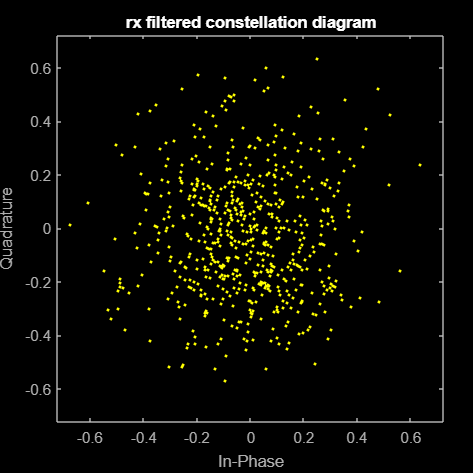


%downsample
% rxSignalDownsampled = downsample(rxSignalFiltered, L);
if counter==nLoops
    figure;
    scatterplot(rxSignalFiltered);
    title('rx filtered constellation diagram');
end


%cp
% rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
rxSymbolsWithCP = reshape(rxSignal, [], numSym);
rxSymbolsWithCP

rxSymbolsWithCP =   -0.1251 - 0.2672i  -0.2557 + 0.0074i   0.1180 + 0.1614i   0.2147 - 0.4823i   0.5409 - 0.2363i   0.1989 + 0.3876i  -0.0955 - 0.5368i  -0.0058 - 0.1358i   0.4382 + 0.6051i  -0.1864 + 0.4384i  -0.2879 - 0.0852i   0.1605 + 0.0209i   0.2885 + 0.1288i  -0.1592 + 0.1111i   0.0591 + 0.1355i  -0.6656 - 0.2499i  -0.0851 - 0.0103i   0.2584 + 0.0877i   0.2732 - 0.0785i  -0.0950 - 0.2252i  -0.3152 + 0.1708i  -0.1341 + 0.3394i  -0.1332 - 0.6557i  -0.0836 - 0.4573i  -0.2665 + 0.2392i  -0.1761 - 0.0328i  -0.2271 + 0.5986i   0.0467 + 0.0276i  -0.2348 - 0.1327i   0.0848 + 0.0507i   0.1311 - 0.3418i   0.1752 + 0.2291i   0.0323 + 0.0004i  -0.6072 + 0.0115i  -0.0518 + 0.1054i  -0.7966 + 0.1046i  -0.1617 + 0.2214i   0.4309 - 0.1292i  -0.3457 - 0.1951i   0.3203 + 0.0868i  -0.0161 - 0.0533i   0.2821 - 0.1831i
  -0.1522 + 0.2378i  -0.2314 - 0.0489i  -0.1094 + 0.2887i   0.0511 - 0.3429i   0.3103 - 0.2509i   0.1429 + 0.1132i  -0.0420 - 0.1206i  -0.3130 - 0.0557i   0.1325 - 0.2153i  -0.2297 + 

rxSymbolsWithCP =    0.0915 - 0.3419i  -0.1574 - 0.4015i   0.1526 + 0.4328i   0.2790 - 0.4422i   0.1245 - 0.3081i  -0.0727 + 0.2323i   0.0365 - 0.5869i  -0.1881 - 0.1173i   0.3872 + 0.6490i   0.0288 + 0.7464i  -0.2643 - 0.0108i   0.0057 + 0.1574i  -0.0501 + 0.4290i  -0.3276 - 0.0567i   0.0988 + 0.3313i  -0.6018 - 0.3088i  -0.1282 + 0.2620i   0.3257 - 0.4079i   0.2946 + 0.0332i   0.0442 - 0.3034i   0.0638 + 0.2695i  -0.2307 + 0.2875i  -0.2695 - 0.7637i  -0.1364 - 0.2622i  -0.0365 + 0.3690i   0.2733 + 0.1211i   0.0221 + 0.3697i  -0.0599 - 0.2760i  -0.1814 - 0.1367i  -0.2064 + 0.0885i   0.1973 - 0.2350i  -0.0650 - 0.0681i   0.2331 + 0.2173i  -0.4052 + 0.2256i  -0.1892 + 0.0558i  -0.4490 + 0.0156i  -0.2224 + 0.2670i  -0.2186 - 0.1657i  -0.4799 - 0.1646i  -0.4002 + 0.2359i   0.1015 - 0.3842i   0.4174 - 0.3942i
   0.0746 + 0.0898i  -0.1796 - 0.1799i  -0.1250 + 0.1126i  -0.2526 - 0.1253i   0.1555 - 0.0585i   0.2149 + 0.2502i   0.2270 + 0.0960i   0.1663 - 0.0364i   0.0062 - 0.2464i  -0.3246 - 

rxSymbolsWithCP =    0.1182 - 0.2272i  -0.1164 - 0.2270i  -0.0819 + 0.4014i   0.4382 - 0.2010i   0.2606 - 0.3116i   0.0805 + 0.2685i   0.2627 - 0.3464i  -0.0568 - 0.2827i   0.5149 + 0.5958i  -0.0429 + 0.3980i  -0.1660 - 0.0940i   0.0677 + 0.1412i   0.0193 + 0.4098i  -0.1906 + 0.2691i   0.2817 + 0.2005i  -0.5648 - 0.3471i   0.0048 - 0.0243i   0.4482 + 0.0223i   0.1141 - 0.0271i  -0.1679 - 0.2440i   0.0635 + 0.3349i   0.1097 + 0.0002i  -0.3680 - 0.5546i   0.1325 - 0.1447i   0.1179 + 0.4157i  -0.0100 + 0.1604i   0.0301 + 0.2481i  -0.1799 - 0.0275i  -0.1339 - 0.1516i   0.2406 + 0.2033i  -0.1897 - 0.5962i  -0.0080 + 0.2199i   0.1340 + 0.0328i  -0.6304 - 0.1193i   0.0460 - 0.0257i  -0.4598 - 0.0565i  -0.2606 + 0.0775i  -0.0744 - 0.1098i  -0.5369 - 0.1148i  -0.1160 + 0.2460i   0.0296 + 0.0000i   0.2076 - 0.0207i
  -0.2939 + 0.2701i  -0.2757 - 0.4529i  -0.1502 + 0.1056i  -0.2003 - 0.0537i   0.3230 - 0.2552i   0.0776 - 0.1095i   0.3807 - 0.0106i  -0.0234 - 0.1951i   0.1329 - 0.2342i  -0.0650 + 

rxSymbolsWithCP =   -0.0467 - 0.1015i  -0.1959 - 0.2361i   0.1394 + 0.3846i   0.2418 - 0.1760i   0.0869 - 0.3117i   0.2792 + 0.3522i   0.0872 - 0.2923i  -0.2931 - 0.0004i   0.4784 + 0.5997i  -0.0613 + 0.4231i  -0.2216 - 0.2960i  -0.0819 + 0.2393i  -0.0163 + 0.3439i  -0.3064 + 0.0203i   0.3046 + 0.3281i  -0.4866 - 0.3633i  -0.1720 + 0.0922i   0.3363 - 0.1136i   0.0717 + 0.0844i  -0.1224 - 0.1558i  -0.0663 + 0.2396i  -0.1145 + 0.1865i  -0.0407 - 0.6489i  -0.0980 - 0.2222i  -0.3065 + 0.4111i  -0.1377 - 0.0598i  -0.1413 + 0.3385i  -0.4517 + 0.0391i  -0.1024 - 0.0390i   0.1614 + 0.1296i   0.0869 - 0.2752i  -0.0220 - 0.2195i  -0.1008 + 0.0992i  -0.6472 + 0.1222i   0.2215 + 0.0973i  -0.4622 + 0.2383i  -0.1785 + 0.0741i  -0.1705 - 0.0595i  -0.5334 - 0.0950i  -0.0892 - 0.0220i  -0.0337 - 0.2031i  -0.0310 - 0.1846i
  -0.1515 + 0.2515i  -0.4253 - 0.1772i   0.0257 + 0.0791i  -0.3330 + 0.2860i   0.1572 - 0.2147i   0.1228 - 0.2346i   0.3675 - 0.1459i   0.0754 + 0.0243i   0.0126 - 0.4352i  -0.3640 + 

rxSymbolsWithCP =   -0.0154 - 0.0066i  -0.2083 - 0.0903i   0.2832 + 0.3523i   0.1467 + 0.0275i   0.3433 - 0.3616i   0.2838 + 0.2153i   0.1016 - 0.4236i  -0.1904 - 0.0740i   0.4861 + 0.5953i  -0.0661 + 0.3364i  -0.2001 - 0.2262i  -0.0773 + 0.0623i  -0.2368 + 0.3201i  -0.1500 - 0.0224i   0.1823 + 0.2156i  -0.5360 - 0.3637i  -0.0282 + 0.0475i   0.1342 - 0.1133i   0.0813 + 0.1066i  -0.1859 - 0.2151i   0.0068 + 0.2035i  -0.1013 + 0.0728i  -0.0849 - 0.6735i   0.1319 - 0.4396i  -0.1761 + 0.4548i   0.0439 - 0.0802i   0.0649 + 0.2521i  -0.0247 + 0.2795i   0.1057 - 0.1173i  -0.1370 + 0.0747i   0.0662 - 0.4707i  -0.0147 + 0.0039i   0.0279 - 0.1518i  -0.6971 - 0.1370i  -0.0668 + 0.2593i  -0.2234 + 0.1738i  -0.1249 - 0.2198i  -0.1170 + 0.0900i  -0.5086 + 0.0303i  -0.0630 - 0.1648i   0.1716 - 0.0728i   0.2616 - 0.2362i
  -0.2197 + 0.2165i  -0.3460 - 0.1629i  -0.1176 + 0.1016i  -0.1598 + 0.0133i  -0.0134 - 0.0845i   0.0580 - 0.1019i   0.1955 - 0.2164i   0.0824 - 0.0311i   0.1382 - 0.2092i  -0.1921 - 

rxSymbolsWithCP =   -0.1100 - 0.0602i  -0.3644 - 0.2175i   0.1198 + 0.4725i   0.1931 - 0.1892i   0.3385 - 0.3220i   0.2990 + 0.2260i   0.1082 - 0.2342i  -0.2154 - 0.1172i   0.4141 + 0.5965i   0.0497 + 0.4595i  -0.0778 - 0.0649i  -0.0917 + 0.2122i  -0.0137 + 0.4108i  -0.1073 + 0.1313i   0.1718 + 0.3016i  -0.4803 - 0.5012i  -0.0684 - 0.0258i   0.2266 + 0.0206i  -0.0513 + 0.1229i  -0.2010 - 0.2712i  -0.1427 + 0.0696i  -0.0165 + 0.2353i  -0.1808 - 0.5510i   0.0576 - 0.4297i  -0.1193 + 0.4883i   0.0058 - 0.0139i  -0.3366 + 0.4150i  -0.1709 + 0.1150i  -0.1708 - 0.1097i   0.0992 + 0.1457i   0.0761 - 0.5959i  -0.1834 - 0.0605i  -0.0037 + 0.1139i  -0.5559 + 0.1384i  -0.0002 + 0.2001i  -0.4053 + 0.1856i  -0.3089 + 0.3016i  -0.2332 + 0.0707i  -0.5662 - 0.0391i  -0.1240 + 0.1112i   0.0394 - 0.1670i   0.1574 - 0.2793i
  -0.1211 + 0.3680i  -0.3621 - 0.0823i  -0.1538 - 0.0068i   0.0477 - 0.1309i   0.2277 - 0.1246i   0.0265 + 0.0147i   0.3291 + 0.0339i  -0.0273 - 0.2091i  -0.0951 - 0.3330i  -0.0530 + 

rxSymbolsWithCP =   -0.0423 - 0.1148i  -0.2484 - 0.1626i   0.1253 + 0.3392i   0.1836 - 0.2885i   0.1724 - 0.2823i   0.0892 + 0.2926i   0.1469 - 0.4020i  -0.3932 - 0.1480i   0.4963 + 0.7083i   0.1046 + 0.4042i  -0.1798 - 0.0787i   0.0736 + 0.1632i  -0.0032 + 0.3776i  -0.0500 + 0.0291i   0.1334 + 0.4255i  -0.4164 - 0.3298i   0.1220 - 0.1465i   0.3924 + 0.0036i   0.1978 + 0.0068i   0.0057 - 0.2107i  -0.0613 + 0.1541i  -0.0744 + 0.2848i  -0.2961 - 0.5964i   0.0266 - 0.3457i  -0.1123 + 0.4942i  -0.0408 - 0.0553i  -0.0490 + 0.5171i  -0.1797 + 0.0956i  -0.0721 + 0.1277i   0.0479 + 0.0671i   0.0047 - 0.5846i  -0.2630 - 0.0275i   0.0580 - 0.0096i  -0.5087 - 0.0969i  -0.0281 + 0.1605i  -0.3374 - 0.0090i  -0.2929 - 0.0416i  -0.1339 - 0.0208i  -0.5994 - 0.2039i  -0.2042 - 0.0583i   0.1460 - 0.2715i   0.2309 - 0.2690i
  -0.0207 + 0.2656i  -0.3036 - 0.2670i  -0.1438 + 0.0420i  -0.2840 - 0.0556i   0.2847 - 0.1614i   0.0532 + 0.0788i   0.3307 + 0.0451i  -0.0941 - 0.0623i   0.1638 - 0.2736i  -0.1627 + 

rxSymbolsWithCP =    0.0297 - 0.1359i  -0.1092 - 0.1440i   0.0360 + 0.3305i   0.1892 - 0.2116i   0.1942 - 0.2735i   0.0638 + 0.2001i   0.2186 - 0.3792i  -0.2625 - 0.1273i   0.5237 + 0.4249i  -0.0897 + 0.4445i  -0.1106 - 0.0663i   0.0658 + 0.0910i   0.0940 + 0.3889i  -0.1897 - 0.0465i   0.2893 + 0.1815i  -0.4670 - 0.3777i  -0.0266 + 0.0652i   0.3296 + 0.1418i   0.0611 + 0.0017i  -0.1182 - 0.2130i   0.0034 + 0.1679i   0.0527 - 0.0557i  -0.2549 - 0.5161i  -0.0083 - 0.3856i  -0.1054 + 0.4581i   0.0837 + 0.0555i  -0.1647 + 0.4352i  -0.2188 + 0.0524i  -0.1473 - 0.1327i  -0.1242 + 0.1080i  -0.0140 - 0.4536i  -0.1495 + 0.1530i  -0.0326 + 0.0520i  -0.6745 + 0.0139i   0.0927 + 0.1320i  -0.3889 + 0.0711i  -0.1388 - 0.0548i   0.0382 + 0.0740i  -0.5448 - 0.1596i  -0.1457 + 0.0235i   0.0664 - 0.2107i   0.0581 - 0.2140i
  -0.0461 + 0.1744i  -0.2442 - 0.1926i  -0.1315 - 0.0522i  -0.1765 - 0.1149i   0.1759 - 0.1345i   0.0273 - 0.1640i   0.2746 + 0.0700i   0.0154 - 0.1629i   0.0062 - 0.3208i  -0.1176 - 

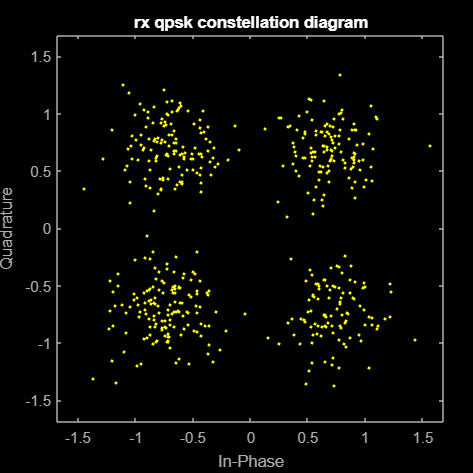

rxSymbols = rxSymbolsWithCP(cpLen+1:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);

if counter==nLoops
    figure;
    scatterplot(rxQPSKSymbols);
    title('rx qpsk constellation diagram');
end


% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(demodulatedBits'~=messageBits(1:dataLength)')

errors = 95

errors = 76

errors = 60

errors = 30

errors = 23

errors = 10

errors = 5

errors = 1

nbiot_ber(counter)=errors/dataLength

nbiot_ber = 0.0942

nbiot_ber =     0.0942    0.0754


nbiot_ber =     0.0942    0.0754    0.0595


nbiot_ber =     0.0942    0.0754    0.0595    0.0298


nbiot_ber =     0.0942    0.0754    0.0595    0.0298    0.0228


nbiot_ber =     0.0942    0.0754    0.0595    0.0298    0.0228    0.0099


nbiot_ber =     0.0942    0.0754    0.0595    0.0298    0.0228    0.0099    0.0050


nbiot_ber =     0.0942    0.0754    0.0595    0.0298    0.0228    0.0099    0.0050    0.0010



symbolRate=samplingRate/SPS

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

bitRate =  2*12*symbolRate

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

EbN0_sim(counter)=SNR*samplingRate/bitRate

EbN0_sim = 6.5000

EbN0_sim =     6.5000    7.0000


EbN0_sim =     6.5000    7.0000    7.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000



SNR_linear = 10^(SNR / 10);
Eb_N0(counter) = (SNR_linear * samplingRate) / bitRate

Eb_N0 = 9.9763

Eb_N0 =     9.9763   12.5594


Eb_N0 =     9.9763   12.5594   15.8114


Eb_N0 =     9.9763   12.5594   15.8114   19.9054


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479   39.7164


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479   39.7164   50.0000


end

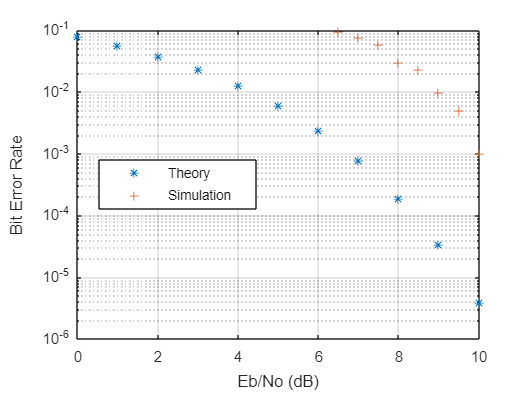

%ber
%https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html
EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(EbN0',ber,'*')
hold on
semilogy(EbN0_sim',nbiot_ber,'+')
legend({'Theory','Simulation'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on